clc
clear

## Settings

read_data = true;
load_models = true;
train_LDA = false;
make_LDA_pred = false;
train_LDA_sep = true;
make_LDA_pred_sep = true;
save_models = false;
save_predictions = false;
save_predictions_sep = true;
plot_conf = true;
new_predict = true;

## Read data

if (read_data)
% Full testing set
FullSet = readtable("results\Data\testing_measured_data_combined.csv");

A.features = [FullSet.c_LO_measured FullSet.c_RE_measured FullSet.f_PLSP_measured...
                FullSet.f_PLSS_measured FullSet.f_LO_measured FullSet.f_LE_measured... 
                FullSet.c_PLS_measured FullSet.c_LE_measured FullSet.c_RaffP_measured...
                FullSet.c_RaffS_measured FullSet.c_BO_measured]

X = A.features;
y = FullSet.state_code;

% Training set
TrainingSet = readtable("results\Data\training_measured_data_combined.csv");

B.features = [TrainingSet.c_LO_measured TrainingSet.c_RE_measured TrainingSet.f_PLSP_measured...
                TrainingSet.f_PLSS_measured TrainingSet.f_LO_measured TrainingSet.f_LE_measured... 
                TrainingSet.c_PLS_measured TrainingSet.c_LE_measured TrainingSet.c_RaffP_measured...
                TrainingSet.c_RaffS_measured TrainingSet.c_BO_measured]

% Testing set - only single faults
SeparateSet = readtable("results\Data\testing_separate_measured_data_combined.csv");

C.features = [SeparateSet.c_LO_measured SeparateSet.c_RE_measured SeparateSet.f_PLSP_measured...
                SeparateSet.f_PLSS_measured SeparateSet.f_LO_measured SeparateSet.f_LE_measured... 
                SeparateSet.c_PLS_measured SeparateSet.c_LE_measured SeparateSet.c_RaffP_measured...
                SeparateSet.c_RaffS_measured SeparateSet.c_BO_measured]
C.y = SeparateSet.state_code;
end

A = struct with fields:
    features: [2073608×11 double]


B = struct with fields:
    features: [1296005×11 double]


C = struct with fields:
    features: [1296005×11 double]


y_C = C.y;

## Load models

if (load_models)
load('results\Models\gaussian_SVM_model.mat');
% 
% load('results\Models\kNN_2comp_model.mat');
% kNN_2comp_model = kNN_final;
% 
% load('results\Models\kNN_4comp_model.mat');
% kNN_4comp_model = kNN_final;

load('results\Models\kNN_model.mat');
kNN_model = final_kNN_model;
% 
% load('results\Models\LDA_2comp_model.mat');
% LDA_2comp_model = lda_final;
% 
% load('results\Models\LDA_4comp_model.mat');
% LDA_4comp_model = lda_final;
end

## Make predictions


X_N = normalize(X);
B_N = normalize(B.features);
C_N = normalize(C.features);
y_B = TrainingSet.state_code;

if (train_LDA)
% Apply LDA for dimensionality reduction 2 components
LDA2.num_components = 2;
lda_model = fitcdiscr(B_N, y_B); % Fit the LDA model
[LDA2.eigenvectors, LDA2.eigenvalues] = eig(lda_model.BetweenSigma, lda_model.Sigma);
[~, LDA2.sorted_indices] = sort(diag(LDA2.eigenvalues), 'descend');
LDA2.projection_matrix = LDA2.eigenvectors(:, LDA2.sorted_indices(1:LDA2.num_components));

% Project training and testing data onto the LDA components
LDA2.B_reduced = B_N * LDA2.projection_matrix;
LDA2.X_reduced = X_N * LDA2.projection_matrix;
kNN_2comp_model = fitcknn(LDA2.B_reduced, y_B, 'NumNeighbors', 90);
LDA_2comp_model = fitcdiscr(LDA2.B_reduced, y_B);

% Apply LDA for dimensionality reduction 2 components
LDA4.num_components = 4;
[LDA4.eigenvectors, LDA4.eigenvalues] = eig(lda_model.BetweenSigma, lda_model.Sigma);
[~, LDA4.sorted_indices] = sort(diag(LDA4.eigenvalues), 'descend');
LDA4.projection_matrix = LDA4.eigenvectors(:, LDA4.sorted_indices(1:LDA4.num_components));

% Project training and testing data onto the LDA components
LDA4.B_reduced = B_N * LDA4.projection_matrix;
LDA4.X_reduced = X_N * LDA4.projection_matrix;
kNN_4comp_model = fitcknn(LDA4.B_reduced, y_B, 'NumNeighbors', 9);
LDA_4comp_model = fitcdiscr(LDA4.B_reduced, y_B);
end

% Train LDA separate
if(train_LDA_sep)
    LDA2.C_reduced = C_N * LDA2.projection_matrix;
    LDA4.C_reduced = C_N * LDA4.projection_matrix;
end

if (save_models)
    save('results/Models/kNN_2comp_model.mat', 'kNN_2comp_model');
    save('results/Models/kNN_4comp_model.mat', 'kNN_4comp_model');
    save('results/Models/LDA_2comp_model.mat', 'LDA_2comp_model');
    save('results/Models/LDA_4comp_model.mat', 'LDA_4comp_model');
end

if (make_LDA_pred)
    [LDA2.y_pred, LDA2.scores, LDA2.cost] = predict(LDA_2comp_model, LDA2.X_reduced);
    
    [LDA4.y_pred, LDA4.scores, LDA4.cost] = predict(LDA_4comp_model, LDA4.X_reduced);
    
    [kNN2.y_pred, kNN2.scores, kNN2.cost] = predict(kNN_2comp_model, LDA2.X_reduced);
    
    [kNN4.y_pred, kNN4.scores, kNN4.cost] = predict(kNN_4comp_model, LDA4.X_reduced);
    % kNN Only
    [kNN.y_pred, kNN.scores, kNN.cost] = predict(kNN_model, X);
    
    % Gaussian SVM
    [SVM_G.y_pred, SVM_G.scores] = gaussian_SVM_model.predictFcn(X);
end

if (make_LDA_pred_sep)
    [LDA2_sep.y_pred, LDA2_sep.scores, LDA2_sep.cost] = predict(LDA_2comp_model, LDA2.C_reduced);
    
    [LDA4_sep.y_pred, LDA4_sep.scores, LDA4_sep.cost] = predict(LDA_4comp_model, LDA4.C_reduced);
    
    [kNN2_sep.y_pred, kNN2_sep.scores, kNN2_sep.cost] = predict(kNN_2comp_model, LDA2.C_reduced);
    
    [kNN4_sep.y_pred, kNN4_sep.scores, kNN4_sep.cost] = predict(kNN_4comp_model, LDA4.C_reduced);
    % kNN_sep Only
    [kNN_sep.y_pred, kNN_sep.scores, kNN_sep.cost] = predict(kNN_model, C.features);
    
    % Gaussian SVM
    [SVM_G_sep.y_pred, SVM_G_sep.scores] = gaussian_SVM_model.predictFcn(C.features);
end


[QDA_app.y_pred, QDA_app.scores] = QDA_app_model.predictFcn(X_N);
[LDA_app.y_pred, LDA_app.scores] = LDA_app_model.predictFcn(X_N);

QDA_app.accuracy = sum(strcmpi(y, QDA_app.y_pred))/length(y)

QDA_app = struct with fields:
        y_pred: {2073608×1 cell}
        scores: [2073608×5 double]
    new_scores: [2073608×4 double]
      accuracy: 0.2364


LDA_app.accuracy = sum(strcmpi(y, LDA_app.y_pred))/length(y)

LDA_app = struct with fields:
           y_pred: {2073608×1 cell}
           scores: [2073608×5 double]
       new_scores: [2073608×4 double]
     new_pred_bin: [1296005×4 double]
         new_pred: [1296005×2 table]
    combined_pred: [1296005×1 string]
         accuracy: 0.5006


if (save_predictions)
    save('results/Predictions/kNN.mat', 'kNN');
    save('results/Predictions/kNN2.mat', 'kNN2');
    save('results/Predictions/kNN4.mat', 'kNN4');
    save('results/Predictions/LDA2.mat', 'LDA2');
    save('results/Predictions/LDA4.mat', 'LDA4');
    save('results/Predictions/SVM_G.mat', 'SVM_G');
end

if (save_predictions_sep)
    save('results/Predictions/kNN_sep.mat', 'kNN_sep');
    save('results/Predictions/kNN2_sep.mat', 'kNN2_sep');
    save('results/Predictions/kNN4_sep.mat', 'kNN4_sep');
    save('results/Predictions/LDA2_sep.mat', 'LDA2_sep');
    save('results/Predictions/LDA4_sep.mat', 'LDA4_sep');
    save('results/Predictions/SVM_G_sep.mat', 'SVM_G_sep');
end

LDA 2 Comp Confusion Matrix:


      910019         177           0         163           0           0           0
      420883       32793           0        2277           0           0           0
        1713         208           0           0           0           0           0
      283643           0           0      104074           0           0           0
        2719           0           0           0           0           0           0
       81336       40293           0      189629           0           0           0
           0           0           0        1536           0           0           0



LDA 4 Comp Confusion Matrix:


      909909         177         168         105           0           0           0
      341020       24237       90696           0           0           0           0
        1747         174           0           0           0           0           0
      283756           0           0      103961           0           0           0
        2719           0           0           0           0           0           0
       46845       39552      146868       77993           0           0           0
           0           0         247        1289           0           0           0



kNN 2 Comp Confusion Matrix:


      544807      310117          12       55423           0           0           0
       70270      287708        2062       95913           0           0           0
         281        1403           0         237           0           0           0
      149378       75579           4      162756           0           0           0
        1317        1341           0          61           0           0           0
        5967       48568         110      256613           0           0           0
           0           0           0        1536           0           0           0



kNN 4 Comp Confusion Matrix:


      711245      119912          32       79170           0           0           0           0
      167013      232725       39849       16366           0           0           0           0
        1289         419           0         213           0           0           0           0
      192383       33220           0      162113           0           0           0           1
        2218         481           0          20           0           0           0           0
      176809       56414       34726       43309           0           0           0           0
        1536           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0



kNN Confusion Matrix:


      876445       33800          67          47           0           0           0
      430972       24981           0           0           0           0           0
        1920           1           0           0           0           0           0
      377998        9719           0           0           0           0           0
        2719           0           0           0           0           0           0
      222050       89208           0           0           0           0           0
        1535           1           0           0           0           0           0



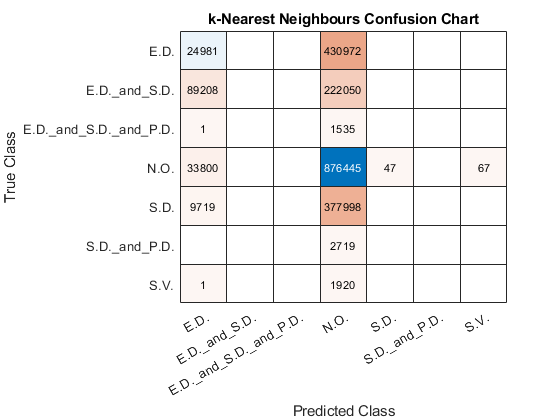

if (plot_conf)
LDA2.mat = confusionmat(y, LDA2.y_pred);
disp('LDA 2 Comp Confusion Matrix:');
disp(LDA2.mat);
confusionchart(y, LDA2.y_pred)
title('LDA 2 comp Confusion Chart');

LDA4.mat = confusionmat(y, LDA4.y_pred);
disp('LDA 4 Comp Confusion Matrix:');
disp(LDA4.mat);
confusionchart(y, LDA4.y_pred)
title('LDA 4 comp Confusion Chart');

kNN2.mat = confusionmat(y, kNN2.y_pred);
disp('kNN 2 Comp Confusion Matrix:');
disp(kNN2.mat);
confusionchart(y, kNN2.y_pred)
title('k-Nearest Neighbours 2 comp Confusion Chart');

kNN4.mat = confusionmat(y, kNN4.y_pred);
disp('kNN 4 Comp Confusion Matrix:');
disp(kNN4.mat);
confusionchart(y, kNN4.y_pred)
title('k-Nearest Neighbours 4 comp Confusion Chart');

kNN.mat = confusionmat(y, kNN.y_pred);
disp('kNN Confusion Matrix:');
disp(kNN.mat);
confusionchart(y, kNN.y_pred)
title('k-Nearest Neighbours Confusion Chart');

% SVM_G.mat = confusionmat(y, SVM_G.y_pred);
% disp('SVM Gaussian Confusion Matrix:');
% disp(SVM_G.mat);
% confusionchart(y, SVM_G.y_pred)
% title('SVM Gaussian Confusion Chart');
end

if (new_predict)
    kNN.new_scores = [kNN.scores(:, 1) kNN.scores(:,3:end)];
    kNN2.new_scores = [kNN2.scores(:, 1) kNN2.scores(:,3:end)];
    kNN4.new_scores = [kNN4.scores(:, 1) kNN4.scores(:,3:end)];
    LDA2.new_scores = [LDA2.scores(:, 1) LDA2.scores(:,3:end)];
    LDA4.new_scores = [LDA4.scores(:, 1) LDA4.scores(:,3:end)];
    SVM_G.new_scores = [SVM_G.scores(:,1) SVM_G.scores(:,3:end)];
end

LDA_app.new_scores = [LDA_app.scores(:, 1) LDA_app.scores(:,3:end)];
QDA_app.new_scores = [QDA_app.scores(:, 1) QDA_app.scores(:,3:end)];

sum(kNN.new_pred_bin)

ans =       258195           0          54         107


% kNN accuracy
threshold = linspace(0, 1, 200); 
for i = 1:200
    kNN.new_pred_bin = zeros(size(kNN.new_scores));
    kNN.new_pred_bin(abs(kNN.new_scores) > threshold(i)) = 1;
    sum(kNN.new_pred_bin);
    kNN.new_pred = table();
    kNN.new_pred.pred = kNN.y_pred;
    kNN.new_pred.label(all(kNN.new_pred_bin == [1 0 0 0], 2)) = "E.D.";
    kNN.new_pred.label(all(kNN.new_pred_bin == [0 1 0 0], 2)) = "P.D.";
    kNN.new_pred.label(all(kNN.new_pred_bin == [0 0 1 0], 2)) = "S.D.";
    kNN.new_pred.label(all(kNN.new_pred_bin == [0 0 0 1], 2)) = "S.V.";
    kNN.new_pred.label(all(kNN.new_pred_bin == [1 0 1 0], 2)) = "E.D._and_S.D.";
    kNN.new_pred.label(all(kNN.new_pred_bin == [1 1 1 0], 2)) = "E.D._and_S.D._and_P.D.";
    kNN.new_pred.label(all(kNN.new_pred_bin == [0 1 1 0], 2)) = "S.D._and_P.D.";
    kNN.new_pred.label(all(kNN.new_pred_bin == [0 0 0 0], 2)) = "N.O.";
    kNN.combined_pred(:, i) = kNN.new_pred.label;
    kNN.accuracy(i) = sum(strcmpi(y, kNN.combined_pred(:, i))) / length(y); 
end 

kNN.accuracy = kNN.accuracy';

[M_kNN, I_kNN] = max(kNN.accuracy);
best_threshold_kNN = threshold(I_kNN); 

% confusionchart(y, kNN.combined_pred(:, I_kNN))
% title('kNN Confusion Chart');
% print('results/Performance/testing/kNN_confchart', '-dpng', '-r600')
% 
% kNN.c = confusionmat(y, kNN.combined_pred(:, I_kNN));
% kNN.c_correct = diag(kNN.c);
% kNN.c_correct_sq = [zeros(7, 1) diag(kNN.c_correct(2:end))];
% kNN.c_faulty = kNN.c(2:end, :);
% kNN.TP = sum(kNN.c_correct_sq, "all");
% kNN.false = kNN.c - diag(kNN.c_correct);
% kNN.FP = sum(kNN.false(:, 2:end), "all");
% kNN.FN = sum(kNN.c(2:end, 1));
% kNN.TN = kNN.c(1,1);
% kNN.precision = kNN.TP/(kNN.TP+kNN.FP);
% kNN.sensitivity = kNN.TP/(kNN.TP+kNN.FN);
% kNN.specificity = kNN.TN/(kNN.TN+kNN.FP);

% kNN2 accuracy
threshold = linspace(0, 1, 200); 
for i = 1:200
    kNN2.new_pred_bin = zeros(size(kNN2.new_scores));
    kNN2.new_pred_bin(abs(kNN2.new_scores) > threshold(i)) = 1;
    sum(kNN2.new_pred_bin);
    kNN2.new_pred = table();
    kNN2.new_pred.pred = kNN2.y_pred;
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [1 0 0 0], 2)) = "E.D.";
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [0 1 0 0], 2)) = "P.D.";
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [0 0 1 0], 2)) = "S.D.";
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [0 0 0 1], 2)) = "S.V.";
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [1 0 1 0], 2)) = "E.D._and_S.D.";
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [1 1 1 0], 2)) = "E.D._and_S.D._and_P.D.";
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [0 1 1 0], 2)) = "S.D._and_P.D.";
    kNN2.new_pred.label(all(kNN2.new_pred_bin == [0 0 0 0], 2)) = "N.O.";
    kNN2.combined_pred(:, i) = kNN2.new_pred.label;
    kNN2.accuracy(i) = sum(strcmpi(y, kNN2.combined_pred(:, i))) / length(y); 
end 

kNN2.accuracy = kNN2.accuracy';

[M_kNN2, I_kNN2] = max(kNN2.accuracy);
best_threshold_kNN2 = threshold(I_kNN2); 

% confusionchart(y, kNN2.combined_pred(:, I_kNN2))
% title('kNN2 Confusion Chart');
% print('results/Performance/testing/kNN2_confchart', '-dpng', '-r600')
% 
% kNN2.c = confusionmat(y, kNN2.combined_pred(:, I_kNN2));
% kNN2.c_correct = diag(kNN2.c);
% kNN2.c_correct_sq = [zeros(7, 1) diag(kNN2.c_correct(2:end))];
% kNN2.c_faulty = kNN2.c(2:end, :);
% kNN2.TP = sum(kNN2.c_correct_sq, "all");
% kNN2.false = kNN2.c - diag(kNN2.c_correct);
% kNN2.FP = sum(kNN2.false(:, 2:end), "all");
% kNN2.FN = sum(kNN2.c(2:end, 1));
% kNN2.TN = kNN2.c(1,1);
% kNN2.precision = kNN2.TP/(kNN2.TP+kNN2.FP);
% kNN2.sensitivity = kNN2.TP/(kNN2.TP+kNN2.FN);
% kNN2.specificity = kNN2.TN/(kNN2.TN+kNN2.FP);

% kNN4 accuracy
threshold = linspace(0, 1, 200); 
for i = 1:200
    kNN4.new_pred_bin = zeros(size(kNN4.new_scores));
    kNN4.new_pred_bin(abs(kNN4.new_scores) > threshold(i)) = 1;
    sum(kNN4.new_pred_bin);
    kNN4.new_pred = table();
    kNN4.new_pred.pred = kNN4.y_pred;
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [1 0 0 0], 2)) = "E.D.";
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [0 1 0 0], 2)) = "P.D.";
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [0 0 1 0], 2)) = "S.D.";
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [0 0 0 1], 2)) = "S.V.";
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [1 0 1 0], 2)) = "E.D._and_S.D.";
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [1 1 1 0], 2)) = "E.D._and_S.D._and_P.D.";
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [0 1 1 0], 2)) = "S.D._and_P.D.";
    kNN4.new_pred.label(all(kNN4.new_pred_bin == [0 0 0 0], 2)) = "N.O.";
    kNN4.combined_pred(:, i) = kNN4.new_pred.label;
    kNN4.accuracy(i) = sum(strcmpi(y, kNN4.combined_pred(:, i))) / length(y); 
end 

kNN4.accuracy = kNN4.accuracy';

[M_kNN4, I_kNN4] = max(kNN4.accuracy);
best_threshold_kNN4 = threshold(I_kNN4); 

% confusionchart(y, kNN4.combined_pred(:, I_kNN4))
% title('kNN4 Confusion Chart');
% print('results/Performance/testing/kNN4_confchart', '-dpng', '-r600')
% 
% kNN4.c = confusionmat(y, kNN4.combined_pred(:, I_kNN4));
% kNN4.c_correct = diag(kNN4.c);
% kNN4.c_correct_sq = [zeros(7, 1) diag(kNN4.c_correct(2:end))];
% kNN4.c_faulty = kNN4.c(2:end, :);
% kNN4.TP = sum(kNN4.c_correct_sq, "all");
% kNN4.false = kNN4.c - diag(kNN4.c_correct);
% kNN4.FP = sum(kNN4.false(:, 2:end), "all");
% kNN4.FN = sum(kNN4.c(2:end, 1));
% kNN4.TN = kNN4.c(1,1);
% kNN4.precision = kNN4.TP/(kNN4.TP+kNN4.FP);
% kNN4.sensitivity = kNN4.TP/(kNN4.TP+kNN4.FN);
% kNN4.specificity = kNN4.TN/(kNN4.TN+kNN4.FP);

% LDA2 accuracy
threshold = linspace(0, 1, 200); 
for i = 1:200
    LDA2.new_pred_bin = zeros(size(LDA2.new_scores));
    LDA2.new_pred_bin(abs(LDA2.new_scores) > threshold(i)) = 1;
    sum(LDA2.new_pred_bin);
    LDA2.new_pred = table();
    LDA2.new_pred.pred = LDA2.y_pred;
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [1 0 0 0], 2)) = "E.D.";
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [0 1 0 0], 2)) = "P.D.";
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [0 0 1 0], 2)) = "S.D.";
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [0 0 0 1], 2)) = "S.V.";
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [1 0 1 0], 2)) = "E.D._and_S.D.";
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [1 1 1 0], 2)) = "E.D._and_S.D._and_P.D.";
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [0 1 1 0], 2)) = "S.D._and_P.D.";
    LDA2.new_pred.label(all(LDA2.new_pred_bin == [0 0 0 0], 2)) = "N.O.";
    LDA2.combined_pred(:, i) = LDA2.new_pred.label;
    LDA2.accuracy(i) = sum(strcmpi(y, LDA2.combined_pred(:, i))) / length(y); 
end 

LDA2.accuracy = LDA2.accuracy';

[M_LDA2, I_LDA2] = max(LDA2.accuracy);
best_threshold_LDA2 = threshold(I_LDA2); 

% confusionchart(y, LDA2.combined_pred(:, I_LDA2))
% title('LDA2 Confusion Chart');
% print('results/Performance/testing/LDA2_confchart', '-dpng', '-r600')
% 
% LDA2.c = confusionmat(y, LDA2.combined_pred(:, I_LDA2));
% LDA2.c_correct = diag(LDA2.c);
% LDA2.c_correct_sq = [zeros(7, 1) diag(LDA2.c_correct(2:end))];
% LDA2.c_faulty = LDA2.c(2:end, :);
% LDA2.TP = sum(LDA2.c_correct_sq, "all");
% LDA2.false = LDA2.c - diag(LDA2.c_correct);
% LDA2.FP = sum(LDA2.false(:, 2:end), "all");
% LDA2.FN = sum(LDA2.c(2:end, 1));
% LDA2.TN = LDA2.c(1,1);
% LDA2.precision = LDA2.TP/(LDA2.TP+LDA2.FP);
% LDA2.sensitivity = LDA2.TP/(LDA2.TP+LDA2.FN);
% LDA2.specificity = LDA2.TN/(LDA2.TN+LDA2.FP);


% LDA4 accuracy
threshold = linspace(0, 1, 200); 
for i = 1:200
    LDA4.new_pred_bin = zeros(size(LDA4.new_scores));
    LDA4.new_pred_bin(abs(LDA4.new_scores) > threshold(i)) = 1;
    sum(LDA4.new_pred_bin);
    LDA4.new_pred = table();
    LDA4.new_pred.pred = LDA4.y_pred;
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [1 0 0 0], 2)) = "E.D.";
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [0 1 0 0], 2)) = "P.D.";
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [0 0 1 0], 2)) = "S.D.";
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [0 0 0 1], 2)) = "S.V.";
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [1 0 1 0], 2)) = "E.D._and_S.D.";
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [1 1 1 0], 2)) = "E.D._and_S.D._and_P.D.";
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [0 1 1 0], 2)) = "S.D._and_P.D.";
    LDA4.new_pred.label(all(LDA4.new_pred_bin == [0 0 0 0], 2)) = "N.O.";
    LDA4.combined_pred(:, i) = LDA4.new_pred.label;
    LDA4.accuracy(i) = sum(strcmpi(y, LDA4.combined_pred(:, i))) / length(y); 
end 

LDA4.accuracy = LDA4.accuracy';


[M_LDA4, I_LDA4] = max(LDA4.accuracy);
best_threshold_LDA4 = threshold(I_LDA4); 

% confusionchart(y, LDA4.combined_pred(:, I_LDA4))
% title('LDA4 Confusion Chart');
% print('results/Performance/testing/LDA4_confchart', '-dpng', '-r600')
% 
% LDA4.c = confusionmat(y, LDA4.combined_pred(:, I_LDA4));
% LDA4.c_correct = diag(LDA4.c);
% LDA4.c_correct_sq = [zeros(7, 1) diag(LDA4.c_correct(2:end))];
% LDA4.c_faulty = LDA4.c(2:end, :);
% LDA4.TP = sum(LDA4.c_correct_sq, "all");
% LDA4.false = LDA4.c - diag(LDA4.c_correct);
% LDA4.FP = sum(LDA4.false(:, 2:end), "all");
% LDA4.FN = sum(LDA4.c(2:end, 1));
% LDA4.TN = LDA4.c(1,1);
% LDA4.precision = LDA4.TP/(LDA4.TP+LDA4.FP);
% LDA4.sensitivity = LDA4.TP/(LDA4.TP+LDA4.FN);
% LDA4.specificity = LDA4.TN/(LDA4.TN+LDA4.FP);


% SVM_G accuracy
threshold = linspace(0, 1, 200); 
for i = 1:200
    SVM_G.new_pred_bin = zeros(size(SVM_G.new_scores));
    SVM_G.new_pred_bin(abs(SVM_G.new_scores) < threshold(i)) = 1;
    sum(SVM_G.new_pred_bin);
    SVM_G.new_pred = table();
    SVM_G.new_pred.pred = SVM_G.y_pred;
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [1 0 0 0], 2)) = "E.D.";
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [0 1 0 0], 2)) = "P.D.";
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [0 0 1 0], 2)) = "S.D.";
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [0 0 0 1], 2)) = "S.V.";
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [1 0 1 0], 2)) = "E.D._and_S.D.";
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [1 1 1 0], 2)) = "E.D._and_S.D._and_P.D.";
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [0 1 1 0], 2)) = "S.D._and_P.D.";
    SVM_G.new_pred.label(all(SVM_G.new_pred_bin == [0 0 0 0], 2)) = "N.O.";
    SVM_G.combined_pred(:, i) = SVM_G.new_pred.label;
    SVM_G.accuracy(i) = sum(strcmpi(y, SVM_G.combined_pred(:, i))) / length(y); 
end 

SVM_G.accuracy = SVM_G.accuracy';

[M_SVM_G, I_SVM_G] = max(SVM_G.accuracy);
best_threshold_SVM_G = threshold(I_SVM_G); 

% 
% confusionchart(y, SVM_G.combined_pred(:, I_SVM_G))

Error using confusionchart (line 68)
Vector of true labels must be of the same type as the vector of predicted labels.

% title('SVM_G Confusion Chart');
% print('results/Performance/testing/SVM_G_confchart', '-dpng', '-r600')
% 
% SVM_G.c = confusionmat(y, SVM_G.combined_pred(:, I_SVM_G));
% SVM_G.c_correct = diag(SVM_G.c);
% SVM_G.c_correct_sq = [zeros(7, 1) diag(SVM_G.c_correct(2:end))];
% SVM_G.c_faulty = SVM_G.c(2:end, :);
% SVM_G.TP = sum(SVM_G.c_correct_sq, "all");
% SVM_G.false = SVM_G.c - diag(SVM_G.c_correct);
% SVM_G.FP = sum(SVM_G.false(:, 2:end), "all");
% SVM_G.FN = sum(SVM_G.c(2:end, 1));
% SVM_G.TN = SVM_G.c(1,1);
% SVM_G.precision = SVM_G.TP/(SVM_G.TP+SVM_G.FP);
% SVM_G.sensitivity = SVM_G.TP/(SVM_G.TP+SVM_G.FN);
% SVM_G.specificity = SVM_G.TN/(SVM_G.TN+SVM_G.FP);

% LDA_app accuracy
threshold = linspace(0, 1, 200); 
for i = 1:200
    LDA_app.new_pred_bin = zeros(size(LDA_app.new_scores));
    LDA_app.new_pred_bin(abs(LDA_app.new_scores) > threshold(i)) = 1;
    sum(LDA_app.new_pred_bin);
    LDA_app.new_pred = table();
    LDA_app.new_pred.pred = LDA_app.y_pred;
    LDA_app.new_pred.label(all(LDA_app.new_pred_bin == [1 0 0 0], 2)) = "E.D.";
    LDA_app.new_pred.label(all(LDA_app.new_pred_bin == [0 1 0 0], 2)) = "P.D.";
    LDA_app.new_pred.label(all(LDA_app.new_pred_bin == [0 0 1 0], 2)) = "S.D.";
    LDA_app.new_pred.label(all(LDA_app.new_pred_bin == [0 0 0 1], 2)) = "S.V.";
    LDA_app.new_pred.label(all(LDA_app.new_pred_bin == [1 0 1 0], 2)) = "E.D._and_S.D.";
    LDA_app.new_pred.label(all(LDA_app.new_pred_bin == [1 1 1 0], 2)) = "E.D._and_S.D._and_P.D.";
    LDA_app.new_pred.label(all(LDA_app.new_pred_bin == [0 1 1 0], 2)) = "S.D._and_P.D.";
    LDA_app.new_pred.label(all(LDA_app.new_pred_bin == [0 0 0 0], 2)) = "N.O.";
    LDA_app.combined_pred = LDA_app.new_pred.label;
    LDA_app.accuracy(i) = sum(strcmpi(y, LDA_app.combined_pred)) / length(y); 
end 

LDA_app.accuracy = LDA_app.accuracy';

% QDA_app accuracy
threshold = linspace(0, 1, 200); 
for i = 1:200
    QDA_app.new_pred_bin = zeros(size(QDA_app.new_scores));
    QDA_app.new_pred_bin(abs(QDA_app.new_scores) < threshold(i)) = 1;
    sum(QDA_app.new_pred_bin);
    QDA_app.new_pred = table();
    QDA_app.new_pred.pred = QDA_app.y_pred;
    QDA_app.new_pred.label(all(QDA_app.new_pred_bin == [1 0 0 0], 2)) = "E.D.";
    QDA_app.new_pred.label(all(QDA_app.new_pred_bin == [0 1 0 0], 2)) = "P.D.";
    QDA_app.new_pred.label(all(QDA_app.new_pred_bin == [0 0 1 0], 2)) = "S.D.";
    QDA_app.new_pred.label(all(QDA_app.new_pred_bin == [0 0 0 1], 2)) = "S.V.";
    QDA_app.new_pred.label(all(QDA_app.new_pred_bin == [1 0 1 0], 2)) = "E.D._and_S.D.";
    QDA_app.new_pred.label(all(QDA_app.new_pred_bin == [1 1 1 0], 2)) = "E.D._and_S.D._and_P.D.";
    QDA_app.new_pred.label(all(QDA_app.new_pred_bin == [0 1 1 0], 2)) = "S.D._and_P.D.";
    QDA_app.new_pred.label(all(QDA_app.new_pred_bin == [0 0 0 0], 2)) = "N.O.";
    QDA_app.combined_pred = QDA_app.new_pred.label;
    QDA_app.accuracy(i) = sum(strcmpi(y, QDA_app.combined_pred)) / length(y); 
end 

QDA_app.accuracy = QDA_app.accuracy';

kNN_sep.accuracy = sum(strcmpi(kNN_sep.y_pred, y_C)) / length(y_C);
kNN2_sep.accuracy = sum(strcmpi(kNN2_sep.y_pred, y_C)) / length(y_C);
kNN4_sep.accuracy = sum(strcmpi(kNN4_sep.y_pred, y_C)) / length(y_C);
LDA2_sep.accuracy = sum(strcmpi(LDA2_sep.y_pred, y_C)) / length(y_C);
LDA4_sep.accuracy = sum(strcmpi(LDA4_sep.y_pred, y_C)) / length(y_C);
SVM_G_sep.accuracy = sum(strcmpi(SVM_G_sep.y_pred, y_C)) / length(y_C);
sep_accuracies = [kNN_sep.accuracy; kNN2_sep.accuracy; kNN4_sep.accuracy; LDA2_sep.accuracy; LDA4_sep.accuracy; SVM_G_sep.accuracy];


full_accuracies = [M_kNN; M_kNN2; M_kNN4; M_LDA2; M_LDA4; M_SVM_G];
combined_accuracies = [sep_accuracies full_accuracies];